# Design LQR Servo Controller in Simulink

This example shows the design of an LQR servo controller in Simulink® using an aircraft autopilot application.

Open the aircraft model.

open_system("lqrpilot")

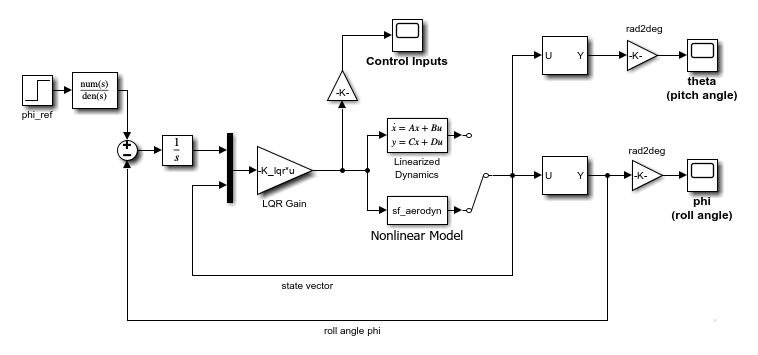

In this model:

- The `Linearized Dynamics` block contains the linearized airframe. 

- `sf_aerodyn` is an S-Function block that contains the nonlinear equations for $\left(\theta ,\phi \right)=\left(0,{15}^{\circ } \right)$.

- The error signal between $\phi$ and the $\phi_{\textrm{ref}}$ is passed through an integrator, which helps drive error to zero.

Opening the model also loads the `lqrpilotData` MAT file, which contains the following data.

- State equation matrices `A` and `B`

- Linearized state matrix `A15`

- Final LQG gain matrix `K_lqr`

## Aircraft State-Space Equations

The equation is the standard state equation of a state-space system.


$$\dot{x} =Ax+Bu$$


For the aircraft system, the state vector is as follows.


$$x={\left\lbrack u,v,w,p,q,r,\theta ,\phi \right\rbrack }^T$$
 

The variables $u$, $v$, and $w$ are the three velocities with respect to the body frame, as shown in the following figure.

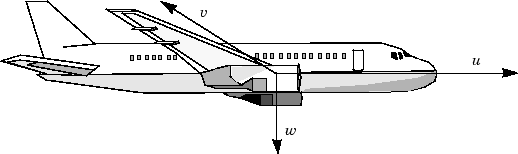

The variables $\phi$ and $\theta$ are roll and pitch. $p$,  $q$, and $r$ are the roll, pitch, and yaw rates, respectively.

The airframe dynamics are nonlinear. The following equation shows the nonlinear components added to the state space equation, where $g$ is the acceleration due to gravity.


$$\dot{x} =\textrm{Ax}+\textrm{Bu}+\left\lbrack \begin{array}{c}
-g\cdot \sin \theta \\
g\cdot \cos \theta \cdot \sin \phi \\
g\cdot \cos \theta \cdot \cos \phi \\
0\\
0\\
0\\
q\cdot \cos \phi -r\cdot \sin \phi \\
\left(q\cdot \sin \phi +r\cdot \cos \phi \right)\cdot \tan \theta 
\end{array}\right\rbrack$$


## Trimming

For LQG design purposes, the nonlinear dynamics are trimmed at $\phi ={15}^{\circ }$ and $p$, $q$, $r$, and $\theta$ set to zero. Since $u$, $v$, and $w$ do not affect into the nonlinear term in the preceding equation, the result is a model linearized around $\left(\theta ,\phi \right)=\left(0,{15}^{\circ } \right)$ with all remaining states set to zero.

The `lqrdes` script shows how to compute the linearized model `A15` at this trimmed operating point.

## Problem Definition

The goal for the design is to perform a steady coordinated turn, as shown in this figure.

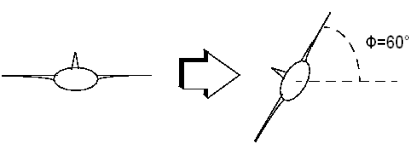

To achieve this goal, you must design a controller that commands a steady turn by going through a 60° roll. In addition, assume that the pitch angle $\theta$ must stay as close to zero as possible.

## Results

The `lqrdes` script shows how to calculate the LQG gain matrix `K_lqr`.

In the `lqrpilot` model, ensure that the switch block is configured to select the output of the Nonlinear Dynamics block.

Run the model.

sim("lqrpilot")

View the response of the roll $\phi$ to a step-change of 60°. The system tracks the commanded roll within about 60 seconds.

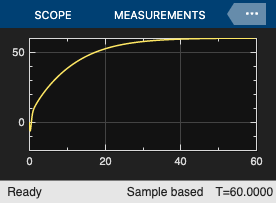

open_system("lqrpilot/phi (roll angle)")

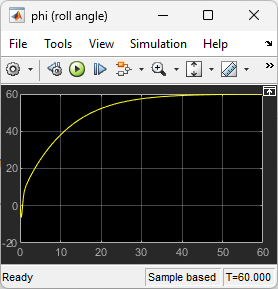

View the pitch angle $\theta$. The controller was able to keep the pitch angle relatively small.

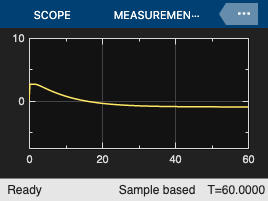

open_system("lqrpilot/theta (pitch angle)")

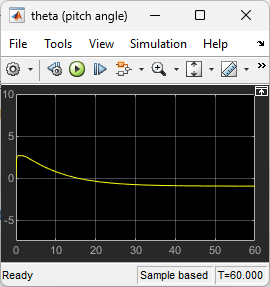

Finally, view the control inputs.

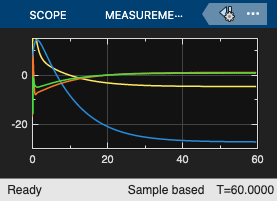

open_system("lqrpilot/Control Inputs")

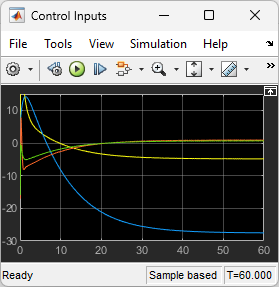

You can adjust the Q and R values in the `lqrdes` script to try different potential designs. Also, you can compare simulations of the linear and nonlinear system dynamics to see the effects of the nonlinearities on the system performance.

*Copyright 2023 The MathWorks, Inc.*